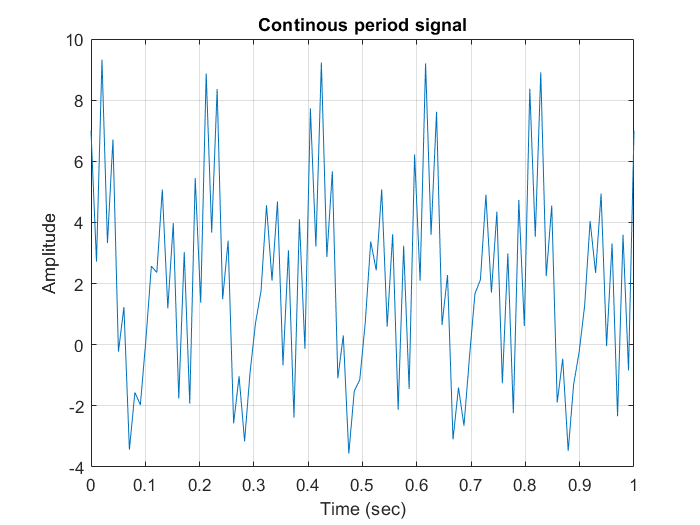

% Homework 1: Perceeption
% Question no: 1
% a
% clear all
% close all
% clc
% x = @(t) 2+3*cos(500*pi*t)+2*cos(1000*pi*t)+3*sin(2000*pi*t);
% t = linspace(0, 1);
% figure(1)
% plot(t, x(t))
% xlabel('Time (sec)')
% ylabel('Amplitude') 
% title('Continous period signal')
% grid
% 
% b
% F_s = 1000;            %Sampling frequency          
% T= 1/Fs;      %Sampling period   
% L = 1000;      %Length of signal
% t = (0:L-1)*T;    %Time vector
% y= fft(x(t));    %Fast Fourier Transform
% P2 = abs(y/L);    %generating spectrum
% P1 = P2(1:L/2+1);
% P1(2:end-1) = 2*P1(2:end-1);
% 
% f = F_s*(0:(L/2))/L;
% figure(2)
% plot(f,P1) 
% xlabel('Frequency (Hz)')
% ylabel('Amplitude') 
% title('Fast Fourier Transform')
% grid

%Question no: 1
% a
clear all
close all
clc
x = @(t) 2+3*cos(500*pi*t)+2*cos(1000*pi*t)+3*sin(2000*pi*t);
t = linspace(0, 1);
figure(1)
plot(t, x(t))
xlabel('Time (sec)')
ylabel('Amplitude') 
title('Continous period signal')
grid

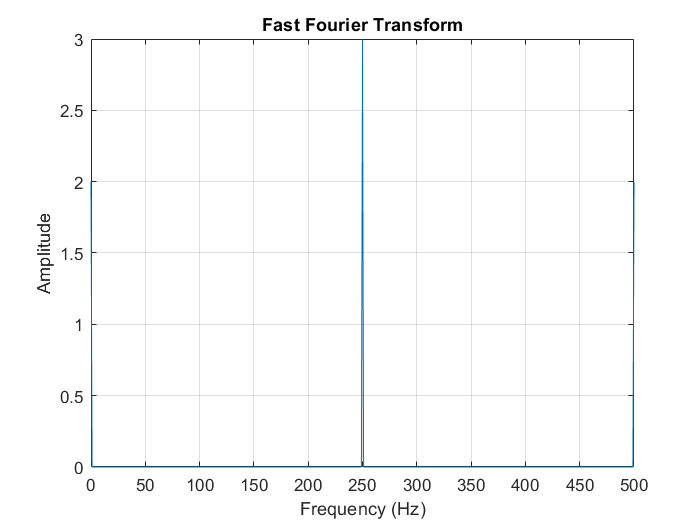


%b
Fs = 1000;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = 1000;             % Length of signal
t = (0:L-1)*T;        % Time vector
y= fft(x(t));         %Fast Fourier Transform


P2 = abs(y/L);        %generating spectrum
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:(L/2))/L;
figure(2)
plot(f,P1) 
xlabel('Frequency (Hz)')
ylabel('Amplitude') 
title('Fast Fourier Transform')
grid

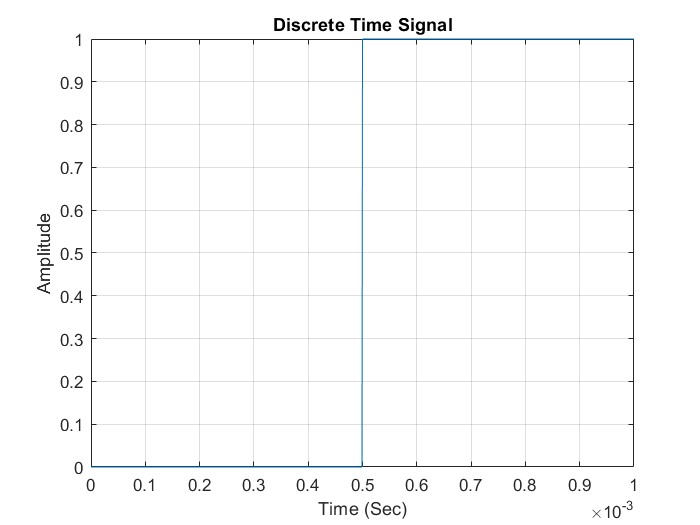

%Question no: 2
% a
clear all
close all
clc

k=0:1:1000;
data= zeros(length(k),1);
for c = 1:length(k)
    if (k(c)>=0) && (k(c)<=499)
        data(c)=0;
    else
        data(c)=1;
    end
end

%%Number of samples:
   N = size(data,1);        % assumes data is an N x 1 column vector
   %%Compute the time domain:
   Fs = 1e6;                % samples per second
   dt = 1/Fs;               % seconds
   t = dt*(0:N-1)';
   T = N*dt;
   %%Plot the time domain signal:
   figure;
   plot(t,data)   
   xlabel('Time (Sec)')
   ylabel('Amplitude') 
   title('Discrete Time Signal')
   grid

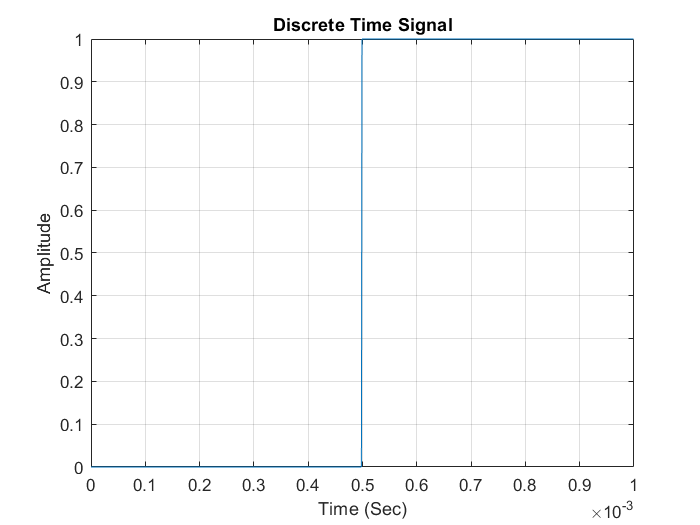



%Question no: 2
% a
clear all
clc
% Setting the Grid Parameters
leftBound = 0;
rightBound = 1000;
numSamples = 1000;

% Generating the grid
k = linspace(leftBound, rightBound, numSamples);
k = k(:);
% % Generating the Discrete Signal
data= zeros(length(k),1);
data(500:length(k))=1;


%%Number of samples:
   N = size(data,1);        % assumes data is an N x 1 column vector
   %%Compute the time domain:
   Fs = 1e6;                % samples per second
   dt = 1/Fs;               % seconds
   t = dt*(0:N-1)';
   T = N*dt;
   %%Plot the time domain signal:
   figure;
   plot(t,data)   
   xlabel('Time (Sec)')
   ylabel('Amplitude') 
   title('Discrete Time Signal')
   grid


%Question no: 2
% b   
   %%two-sided spectrum, centered on DC
   X = fftshift(fft(data))/N;     
   %%Compute the frequency domain:
   dF = Fs/N;
   f = (-Fs/2:dF:Fs/2-dF)';   
   %%Plot the frequency domain signal:
   figure;
   plot(f,abs(X));
   hold on 
   yline(max(abs(X))/2^(1/2))
   xlabel('Frequency (Hz)')
   ylabel('Amplitude') 
   title('Fast Fourier Transform')
   grid

% bw - 3db Bandwidth
    %flo: Bandwidth frequency low, fhi: Bandwidth frequency High
    [bw,flo,fhi,powr] = powerbw(data,1000)

bw = 0.7641

flo = 0

fhi = 0.7641

powr = 0.3045

     fprintf('The 3-dB (half-power) bandwidth is %d . \n',bw);

The 3-dB (half-power) bandwidth is 7.640781e-01 . 


     fprintf('The lower and upper bound frequecy are %d & %d respectively . \n',flo,fhi);

The lower and upper bound frequecy are 0 & 7.640781e-01 respectively . 


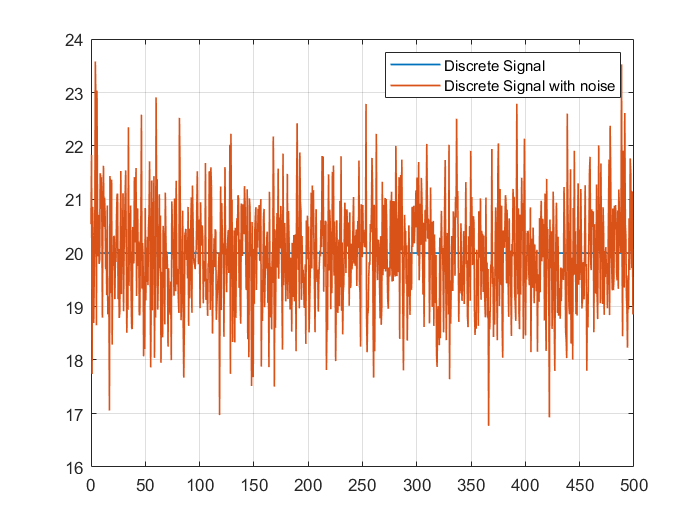


%%3.
% Setting the Grid Parameters
leftBound = 0;
rightBound = 499;
numSamples = 1000;

% Generating the grid
k = linspace(leftBound, rightBound, numSamples);
k = k(:);
samplingInterval    = mean(diff(k));

% % Generating the Discrete Signal
X_k(1:length(k))=20;
% %Adding a normally distributed noise with variance 1
X_k1 =X_k  + 1*normrnd(0,1,[1,length(k)]);
%solution for a
figure(1)
plot(k,X_k,k,X_k1, 'LineWidth',1)
legend({['Discrete Signal'], ['Discrete Signal with noise']})
grid


% Applying low pass filter
windowSize = [3,11]; 
sigma_3=3;
sigma_11=11;

% Signals Parameters
gaussianKernelStd   = [3,11];
sigma  = 1;
%Generating the Gaussian Kernel
vkx=fspecial('gaussian',[1,gaussianKernelStd(1)],sigma)

vkx =     0.2741    0.4519    0.2741


vky=fspecial('gaussian',[1,gaussianKernelStd(2)],sigma)

vky =     0.0000    0.0001    0.0044    0.0540    0.2420    0.3989    0.2420    0.0540    0.0044    0.0001    0.0000


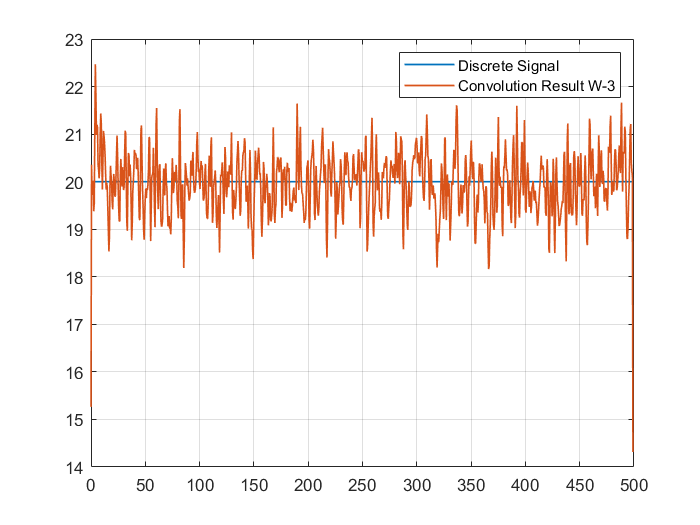

Y_k_3 = conv(X_k1, vkx, 'same');
Y_k_11 = conv(X_k1, vky, 'same');

%solution for b
figure(2)
%plot(k,[X_k,Y_k_3]);
plot(k,X_k,k,Y_k_3, 'LineWidth',1)
legend({['Discrete Signal'], ['Convolution Result W-3']});
grid

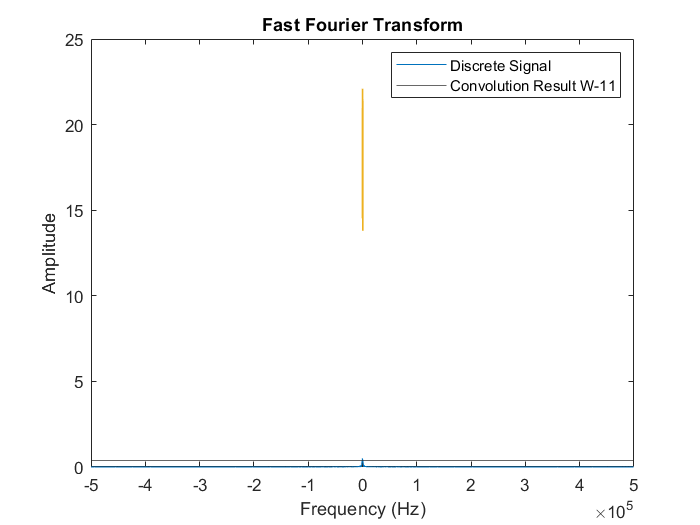


%solution for c
figure(3)
plot(k,X_k,k,Y_k_11, 'LineWidth',1)
legend({['Discrete Signal'], ['Convolution Result W-11']});
grid